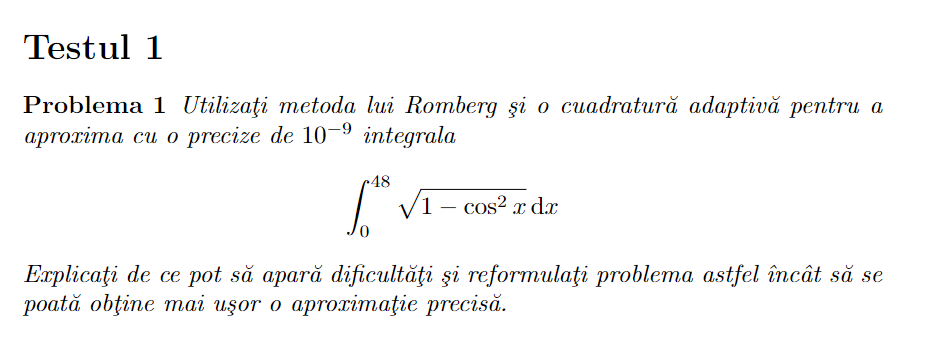

syms x
f = @(x) (1 - cos(x).^2);
prec = 1e-9;

vi=int(1 - cos(x).^2,[0, 48]);
ve=double(vi);

% metoda lui Romberg
format long
[I, nfev] = Romberg(f, 0, 48, prec, 100)

ans =   14.165165391493010                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
  26.764314769376902  30.964031228671534                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
  28.640586870309765  29.266010903954054  29.152809548972886                   0                   0                   0                   0                   0                   0                   0                   0                   0
  29.069932055847104  29.213047117692884  29.209516198608807  29.210416304158581                   0                   0                   0                   0                   0                   0                   0                   0
  29.175087330538521  29.21013

I =   23.754103063641427


nfev =         2049


abs(I - ve)

ans =      1.421085471520200e-14


% cuadratura adaptiva
syms x
[Q,fcount] = adquad(f, 0, 48, prec)

Q =   23.754103063641285


fcount =         4025


abs(Q - ve)

ans =      1.278976924368180e-13


% verificam cu integral
Q2 = integral(f, 0, 48, 'AbsTol', prec)

Q2 =   23.754103063641409


abs(Q2 - ve)

ans =      3.552713678800501e-15


Observam ca **o aproximare folosind metoda lui Romberg este mai fina decat calculul clasic al integralei, insa nu atat de precisa precum aproximarea folosind o cuadratura adaptiva**. Aceasta se datoreaza faptului ca intervalul este destul de mare, iar la majoritatea metodelor de integrare numerica erorile depind de lungimea intervalului.

Cuadraturile adaptive folosesc principiul **Divide et Impera** - asadar ar fi o idee buna sa impartim intervalul original in subintervale si sa utilizam 2 metode diferite pe fiecare subinterval, asigurandu-ne ca **o metoda supraestimeaza rezultatul, iar cealalta il subestimeaza**.

Q3 = adquadDivideEtImpera(f, 0, 48, prec, @Romberg)

ans =   14.165165391493010                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
  26.764314769376902  30.964031228671534                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
  28.640586870309765  29.266010903954054  29.152809548972886                   0                   0                   0                   0                   0                   0                   0                   0                   0
  29.069932055847104  29.213047117692884  29.209516198608807  29.210416304158581                   0                   0                   0                   0                   0                   0                   0                   0
  29.175087330538521  29.21013

ans =   14.165165391493010                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
  26.764314769376902  30.964031228671534                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
  28.640586870309765  29.266010903954054  29.152809548972886                   0                   0                   0                   0                   0                   0                   0                   0                   0
  29.069932055847104  29.213047117692884  29.209516198608807  29.210416304158581                   0                   0                   0                   0                   0                   0                   0                   0
  29.175087330538521  29.21013

Q3 =   23.754103063641427


abs(Q3 - ve)

ans =      1.421085471520200e-14
